# Replicating Frässle et al. (2021) simulations

Why are my RMSE values so different than what is produced in Frässle et al. 

Can I replicate one of the networks used in their simulations to see if I can get RMSE's closer to the values they report in Frässle et al. (2021)?

E.g. model 4: four node network with 3 connectivity parameters (25% sparsity)

stim_options = get_default_stim_options();
nr = 4;

model4 = zeros(nr, nr);
model4(2, 1) = 1;
model4(3, 2) = 1;
model4(4, 3) = 1;

stim_options.n = nr;
stim_options.T = 300;
stim_options.A = ones(nr, nr);
stim_options.C = zeros(nr, nr);
stim_options.a = ones(nr, nr);
stim_options.c = zeros(nr);

num_sims = 20;
type = 'r';
methods = 2;
output_all =  cell(1, num_sims);

Confirm you have the same SNR and TR settings

stim_options.SNR

ans = 3

stim_options.TR

ans = 2

Simulate 20 subjects by

- chenge true connectivity matrix in `stim_options`

- generate timeseries

- remove input used for the AR(1) process

- invert model using pruning

for i=1:num_sims
    
    counter = 0;
    maxIter = 10;
    origState = warning;
    
    while counter<maxIter
        
        if counter == 0
            fprintf("First try.\n");
        end
        
        % Sample connectivity parameters and make sure they are >0.05
        too_small = 1;
        while too_small
            sampled_as = randn(4);
            stim_options.Tp.A = sampled_as.*model4;
            too_small = sum(sum(abs(stim_options.Tp.A)>0 & abs(stim_options.Tp.A)<0.05))
        end
       
       
        % Sample hemodynamic parameters
%         stim_options.transit
%         stim_options.decay
%         stim_options.epsilon
        
        warning('off');
        [DCM, options] = make_DEM_demo_induced_fmri(stim_options);
        [warnMsg, warnId] = lastwarn;
        
        %if there is a warning then increase the counter and try again
        if ~isempty(warnMsg)
            counter = counter + 1
%             sprintf("Got warning. Trying again. Counter = %.0f.\n", counter);
        %if no warning push counter to quit the while loop
        else
            counter = maxIter + 1;
            fprintf("No warnings.\n");
        end
        
        % Clear last warning message
        warning(''); 
    end
    warning(origState);

    
    if isfield(DCM, "U")
        DCM = rmfield(DCM,'U');
    end
    
    options.p0_all = 0.05:0.1:0.95;
    [output, options] = tapas_rdcm_estimate(DCM, type, options, methods);
    output_all{i} = output;
end

First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 1

too_small = 0

counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results


Get RMSE for each simulation

rmses = zeros(length(output_all),1);

for i=1:length(output_all)
    true_a = reshape(output_all{i}.allParam.par_true(1:nr*nr),4, 4);
    est_a = reshape(output_all{i}.allParam.par_est(1:nr*nr),4, 4);
    rmses(i) = get_rmse(true_a, est_a);
end

What is the distribution of rmse's?

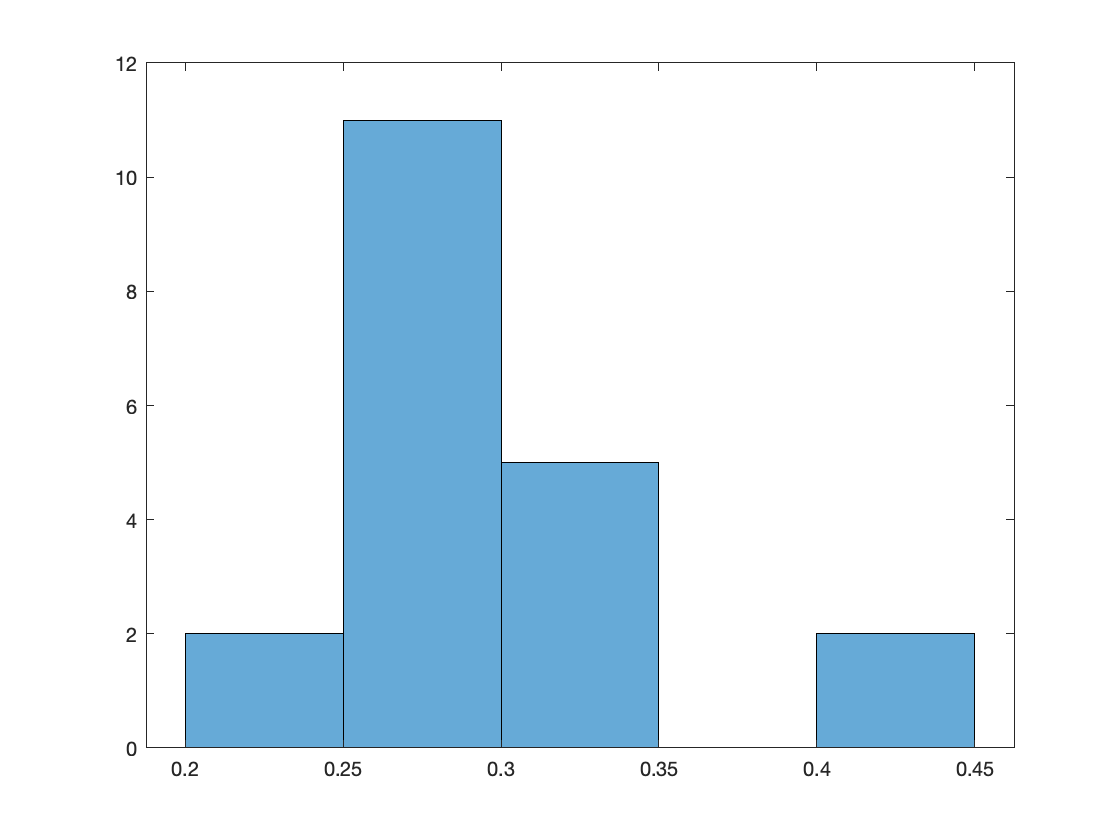

histogram(rmses)

Our RMSE's are still a lot higher. What might be different?

- Model 4 is supposed to estimate 3 parameters. So should it not estimate the diagonals? (which makes the number non-zero parameters in A 7)

- Distribution for true A parameters?

- For the sake of speed in this notebook sampling p0 from more coarsely

- They also sampled hemodynamic parameters which was supposed to make things harder for rDCM. In this notebook they are fixed which should help rDCM.

**Does things look better if you used the original model without sparsity constraints?**

output_all_ridge =  cell(1, num_sims);

for i=1:num_sims
    
    counter = 0;
    maxIter = 10;
    origState = warning;
    
    while counter<maxIter
        
        if counter == 0
            fprintf("First try.\n");
        end
        
        % Sample connectivity parameters and make sure they are >0.05
        too_small = 1;
        while too_small
            sampled_as = randn(4);
            stim_options.Tp.A = sampled_as.*model4;
            too_small = sum(sum(abs(stim_options.Tp.A)>0 & abs(stim_options.Tp.A)<0.05))
        end
        
        warning('off');
        
        %remove the stim_options.a to get ridge to work instead of pruning
        if isfield(stim_options, "a")
            stim_options = rmfield(stim_options,'a');
        end
        
        [DCM, options] = make_DEM_demo_induced_fmri(stim_options);
        [warnMsg, warnId] = lastwarn;
        
        %if there is a warning then increase the counter and try again
        if ~isempty(warnMsg)
            counter = counter + 1
%             sprintf("Got warning. Trying again. Counter = %.0f.\n", counter);
        %if no warning push counter to quit the while loop
        else
            counter = maxIter + 1;
            fprintf("No warnings.\n");
        end
        
        % Clear last warning message
        warning(''); 
    end
    warning(origState);

    
    if isfield(DCM, "U")
        DCM = rmfield(DCM,'U');
    end
    
    [output, options] = tapas_rdcm_estimate(DCM, type, options, 1);
    output_all_ridge{i} = output;
end

First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results
